# Theta Plotter

Plots the position of the ABB-2600-12/1.85 Robot for a given configuration defined by theta angles at each joint.

## User Parameters

% Home Position
theta = [0 0 0 0 0 0];

% Position O
%theta = [0.0598    0.0437   -0.6301    0.1078   -0.5891    3.0519];

% Position A
%theta = [0.0222   -0.6604   -0.4992         0    0.4112   -1.5486 0];

## Plot Generation

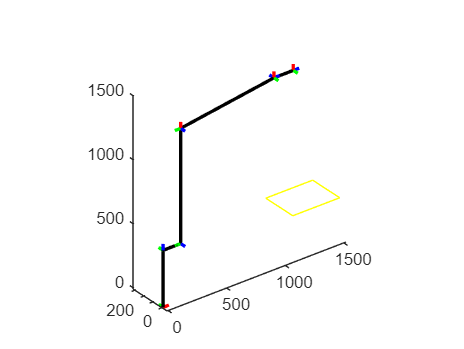

op =   1×3 Line array:

    Line    Line    Line


% Create a new Plot
outputPlot = figure(1);
view(3);
hold on;
[op, ~, ~, ~] = ABB_Plot(theta(1,:), 1, outputPlot)

theta = rad2deg(theta)

theta =      0     0     0     0     0     0



% Output T_60
[~, a, d, DH] = ABB_Config();
T_60 = subsSymToT(DH, 6, 0, theta, a, d)

T_60 =            0           0           1         945
           0          -1           0           0
           1           0           0        1460
           0           0           0           1


T_70 = subsSymToT(DH, 7, 0, theta, a, d)

T_70 =            0           0           1        1110
           0          -1           0           0
           1           0           0        1460
           0           0           0           1
